# Examen RA3L "intro Matlab"      12/11/2022  08h30 -> 10h00 

% Nom :      ADDDA                                      /10
% Prénom :    SABIR  
% Matricule :   

Dans le cadre d'une expérience sur la mesure de la température dans un four, il a été demandé d'étudier et de revoir le choix de la sonde permettant le contr**ô**le de la température à l'intérieur du four. Dans ce four, la température est comprise entre 25 et 300°C et est mesurée via un thermocouple et contr**ô**lée via une thermorésistance Pt100.

Il est maintenant décidé de remplacer la Pt100 pour le contr**ô**le par une thermistance NTC. Pour vérifier ce choix, (et donc comparer la Pt100 et la NTC), des données ont été mesurées et enregistrées durant la chauffe du four dans le fichier Data_four.mat : 

- Theta : La mesure de la température de référence via un thermocouple permettant la régulation du four en température en °C. 

- R_Pt100 : La mesure de la résistance aux bornes de la Pt100 en ohms. 

- R_NTC : La mesure de la résistance aux bornes de la NTC en ohms. 

clear all, close all
load data_four.mat
whos;

  Name         Size            Bytes  Class     Attributes

  R_NTC        1x9                72  double              
  R_Pt100      1x20              160  double              
  Theta        1x20              160  double              



**1)** **Récupérez les données mesurées pour la Pt100 et la NTC depuis le fichier "Data_four.mat". **

Sachant que la sonde NTC ne mesure pas des valeurs de température supérieures ou égales à 150°C, **créer un nouveau vecteur **(Theta_1 et R_Pt100_1) **contenant les températures ****strictement inférieures**** à 150°C. **Utiliser ces vecteurs raccourcis pour le reste de l'exercice. 

**Afficher, **dans une figure avec deux graphique**s**, **les données en fonction des valeurs de résistances pour les deux sondes en fonction de la température de référence. ***(1.5 point)*

Résultat attendu : 

NB : Concernant les unités de l'axe des y, utiliser la notation suivante : [Ohm]. L'implémentation du symbole Omega est un bonus.

 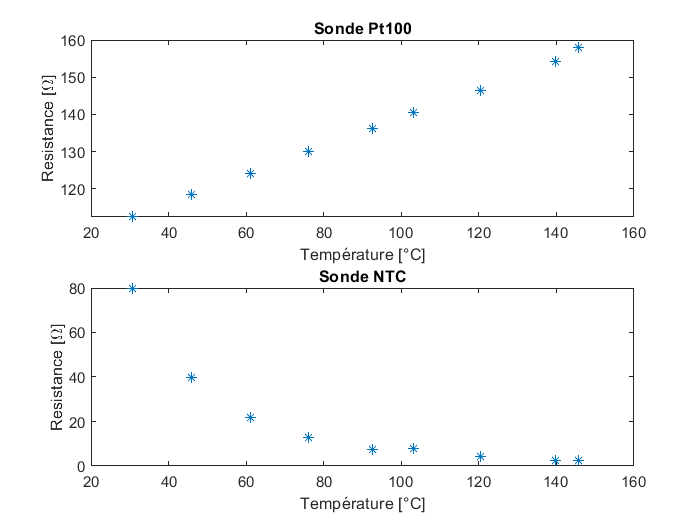

**2)** **Ajuster, via Matlab, les valeurs des coefficients **$R_0$ et $\alpha$ **de l'équation** $R=R_0 *\left(1+\alpha *\theta \right)$ **de la Pt100 pour trouver la droite qui passe au plus près des points expérimentaux Theta_1 et R_Pt100_1 (au sens des moindres carrés)**. Utiliser R0 pour $R_0$ et alpha pour $\alpha$ dans votre code. 

**Créer ensuite une fonction handle "Pt100" qui contient l'expression de l'équation caractéristique de la Pt100 exprimé ci-dessus. **Cette fonction sera utilisé plus tard dans l'exercice. *(2 points)*

**3)** Nous souhaitons ensuite ajuster (fiter) la courbe caractéristique paramétrique de la NTC pour les points expérimentaux. **Ajustez les 2 paramètres (**$R_0$ et $\beta$**) de la ****courbe** $R=R_0 *e^{\left(\beta \left(\frac{1}{\theta +273\ldotp 15}-\frac{1}{\theta_0 }\right)\right)}$**pour "coller" au sens des moindres carrés aux points expérimentaux.** Utiliser, dans l'équation, $\theta_0 =25+273,15$ comme valeur de température de référence. *(2 points)*

**3 bis)** **Calculer et stocker le résultat du coût** pour des valeurs de $R_0 =0\;à\;300\;\Omega \;$(par pas de 1) et des valeurs de $\beta =3000\;à\;6000$ (pas de 10) dans une matrice nommée "cout" et en extraire la valeur du coût minimum et des valeurs de et de correspondantes. *(1.5 point)*

*NB : Si vous n'arrivez pas à faire cette question dans un premier temps, passez-la et revenez-y après avoir finalisé les questions 4 et 5 (ci-dessous). *

[BONUS] : Afficher ensuite, en 3D à l'aide de la commande "mesh", le coût en fonction des 2 paramètres $R_0$ et $\beta$.

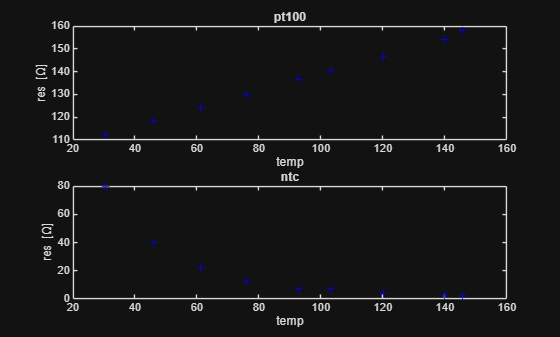

%Code

Résulat attendu : 

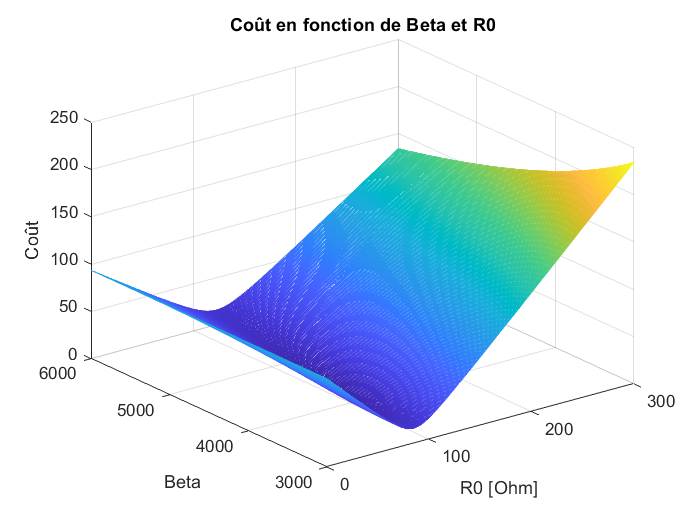

**4) Tracer**, dans une figure contenant le graphe de la Pt100 (en haut) et celui de la NTC (en bas),** les points expérimentaux et la courbe caractéristique ajustée à la sonde concernée **pour 200 points entre 25°C et 150°C**.** (1 points)

NB : Si vous n'avez pas réussi la question 2 et/ou la 3, utiliser les valeurs suivantes pour tracer la/les courbe(s) théorique(s) : 

- Valeurs théoriques Pt100 : $R_0 =100\;$ et $\alpha =0\ldotp 00385$,

- Valeurs théoriques NTC : $R_0 =100\;$et $\beta =4050$ et $\theta_0 =25+273\ldotp 15$

Résulat attendu : 

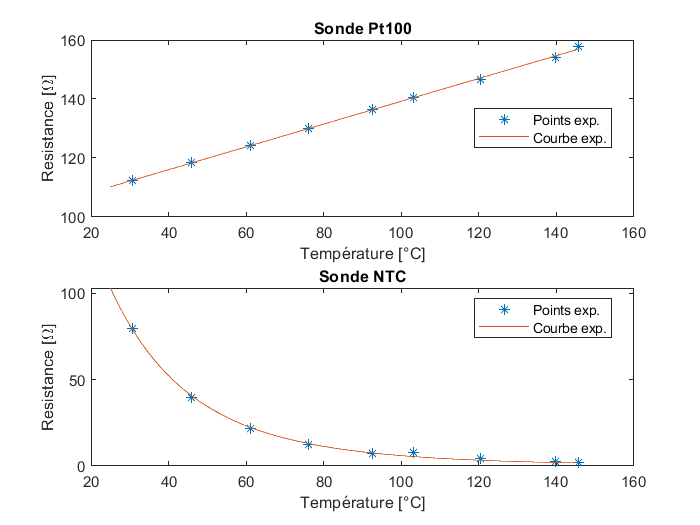

%Code


**5)** Le but de cette sous-question est de comparer l'ajustement de courbes paramétriques réalisé précédement (questions 2 et 3) à une interpolation des données expérimentales fournies dans le fichier "Data_four.mat". Pour ce faire, **créer une fonction explicite "calc_erreur" qui calcule ****la moyenne de la valeur absolue de la différence**** entre les valeurs de résistance obtenues via les courbes ajustées (cf. questions 2 et 3) et via une interpolation cubique **(méthode "cubic" ou "pchip")** entre les données de départ**.

 En pratique, la fonction sera appelée 2 fois (une fois pour les paramètres correspondants à la Pt100 et une fois pour les paramètres correspondants à la NTC) et aura comme entrées : 

- les 200 températures entre 25°C et 150°C (cf. Q4) ;

- les valeurs de résistance de la Pt100 ou de la NTC obtenues à ces températures via les fonction handle (cf. Q2-3)

- les températures expérimentales (variable Theta_1)

- les valeurs expérimentales de résistance (variable R_Pt100_1 ou R_NTC, en fonction de la sonde étudiée) 

*(2 points)*

Résulats attendus : 

erreur_Pt100 = 0.2160 ohm

erreur_NTC = 0.8328 ohm

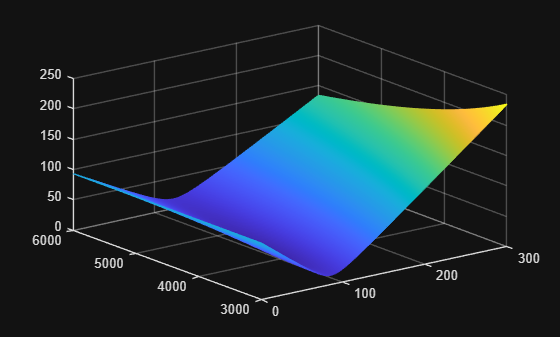

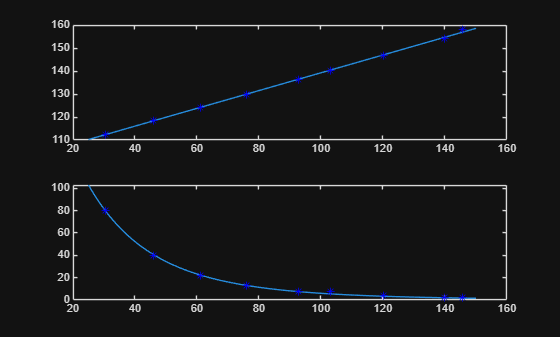

pt100 = 0.2619

ntc = 0.8223

%Code

